# Lab 4

## Section 1 - H = Vout/Vin

H = Vout / Vin

syms s R1 R2 C
Zc = 1/(s * C)

$$Zc = \frac{1}{C\,s}$$

Zs = simplifyFraction(R1 + Zc)

$$Zs = \frac{C\,R_{1}\,s+1}{C\,s}$$

H = simplifyFraction(Zs / (R1 + Zs))

$$H = \frac{C\,R_{1}\,s+1}{2\,C\,R_{1}\,s+1}$$

R1 = 4; R2 = 2; C = 3;
H = subs(H)

$$H = \frac{12\,s+1}{24\,s+1}$$

## Section 2 - Impulse and Step

% Convert Symbolic Equation to numerator and demoninator row vectors
[symNum, symDen] = numden(H)

$$symNum = 12\,s+1$$

$$symDen = 24\,s+1$$

num = sym2poly(symNum)

num =     12     1


den = sym2poly(symDen)

den =     24     1



% Create a continuous-time model of the transfer function
HTF = tf(num, den)

HTF =
 
  12 s + 1
  --------
  24 s + 1
 
Continuous-time transfer function.
Model Properties


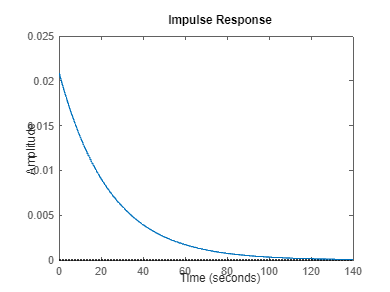


% Check for stability using impulse
impulse(HTF)


% Check for stability using poles
roots(den)

ans = -0.0417

pole(HTF)

ans = -0.0417

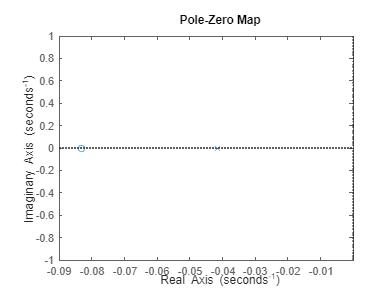

pzmap(HTF)

## Section 3

syms s R2 C2
Zc = 1/(s*C2)

$$Zc = \frac{1}{C_{2}\,s}$$

Zs = simplifyFraction(R2 + Zc + 1 * s)

$$Zs = \frac{C_{2}\,s^{2}+C_{2}\,R_{2}\,s+1}{C_{2}\,s}$$

H = simplifyFraction(Zc / Zs)

$$H = \frac{1}{C_{2}\,s^{2}+C_{2}\,R_{2}\,s+1}$$

H = subs(H)

$$H = \frac{1}{C_{2}\,s^{2}+C_{2}\,R_{2}\,s+1}$$

## Section 4-1 

% Overdamped, didnt overshoot but takes longer than critical to get to the
% value and has two distinct poles
%R2 = 5; C2 = 4;
% Underdamped, has two complex poles that are conjugates
%R2 = 1; C2 = 1;
% Critically Damped, has two poles at the exact same spot that are real
R2 = 1; C2 = 4;

H = subs(H)

$$H = \frac{1}{4\,s^{2}+4\,s+1}$$


% Convert Symbolic Equation to numerator and demoninator row vectors
[symNum, symDen] = numden(H)

$$symNum = 1$$

$$symDen = 4\,s^{2}+4\,s+1$$

num = sym2poly(symNum)

num = 1

den = sym2poly(symDen)

den =      4     4     1



% Create a continuous-time model of the transfer function
HTF = tf(num, den)

HTF =
 
         1
  ---------------
  4 s^2 + 4 s + 1
 
Continuous-time transfer function.
Model Properties


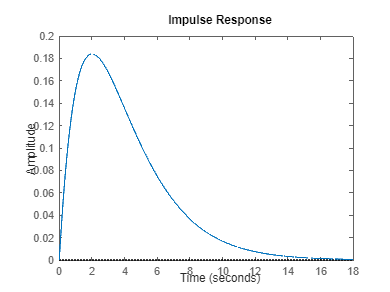


% Check for stability using impulse
impulse(HTF)


% Check for stability using poles
roots(den)

ans =    -0.5000
   -0.5000


pole(HTF)

ans =    -0.5000
   -0.5000


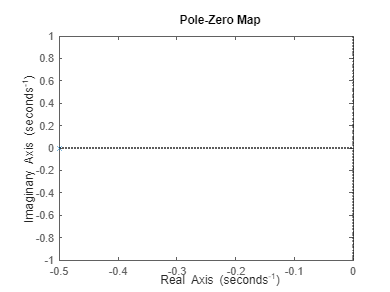

pzmap(HTF)

## Section 4-2

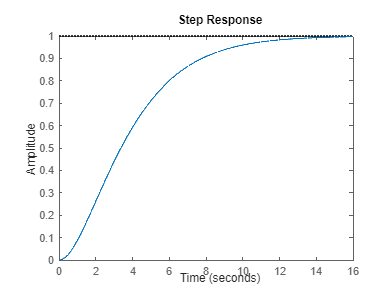

%Overdamped
step(HTF)